# ergoCub Finger PID tuning

Copyright (C) 2023 Fondazione Istitito Italiano di Tecnologia (IIT)

All Rights Reserved.

## System identification and modelling 

### Read and plot datasets

#### Training Set

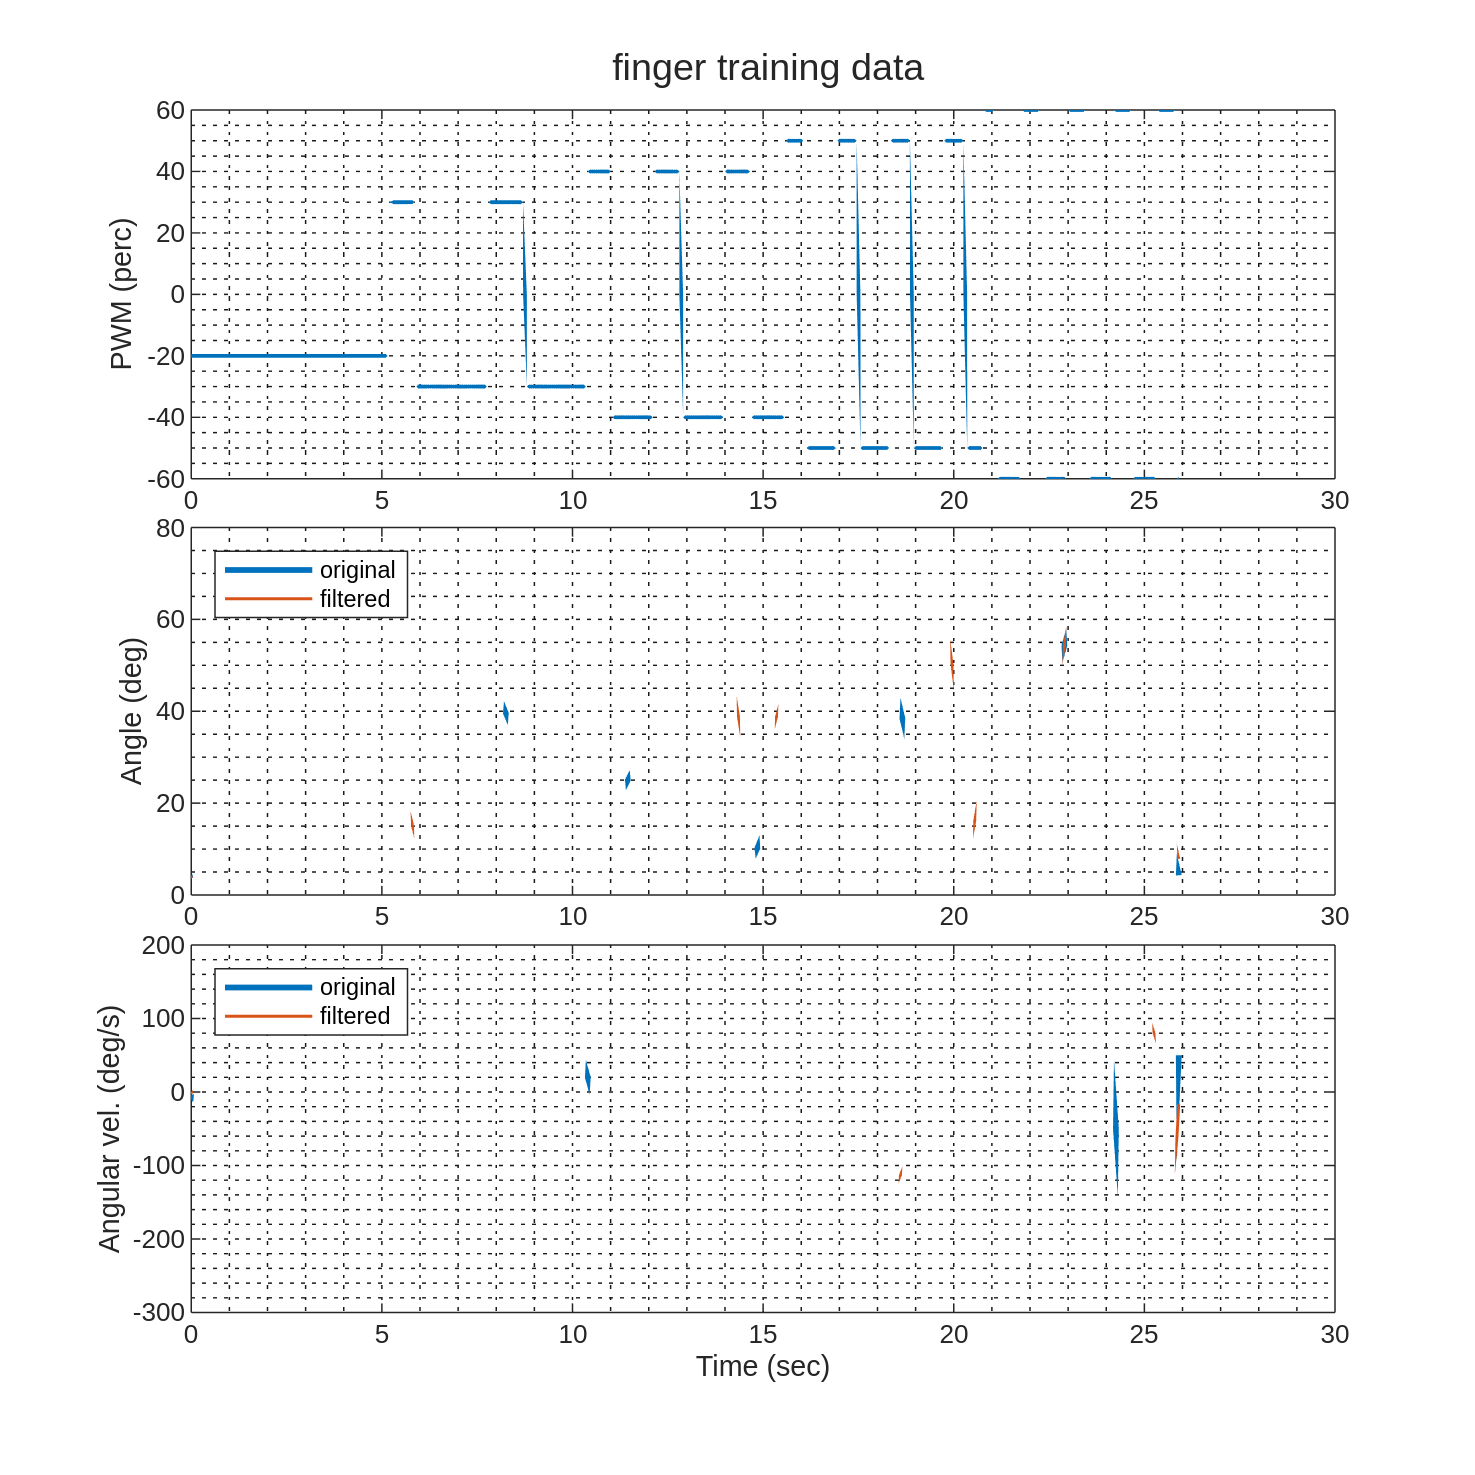


if(~exist('fname', 'var') ||  ~exist('fpath', 'var'))
    [fname, fpath] = uigetfile('*');
end
[nameFile] = fileparts(fname);

filter_constant = 1;
[training_table, Ts] = Reshape_dataset(fullfile(fpath,fname),  filter_constant, 1, 0, 2);

training_data = iddata(training_table.vel, training_table.pwm, Ts);
training_data.Name = "training";

f_train = figure('color', 'white','Position',[10 10 590 590]);
tiledlayout(3,1, "TileSpacing", "tight")

h1 = nexttile;
plot(training_table.Time, training_table.pwm);
ylabel("PWM (perc)")
h2 = nexttile;
plot(training_table.Time, training_table.pos_uf,'LineWidth',2);
hold on
plot(training_table.Time, training_table.pos,'LineWidth',1);
ylabel("Angle (deg)")
legend({"original", "filtered"},'Location','northwest')
h3 = nexttile;
plot(training_table.Time, training_table.vel_uf ,'LineWidth',2);
hold on
plot(training_table.Time, training_table.vel,'LineWidth',1);


legend({"original", "filtered"},'Location','northwest')
ylabel("Angular vel. (deg/s)")
xlabel("Time (sec)")

linkaxes([h1 h2 h3], 'x')
sgtitle(strcat(nameFile, " finger training data"), Interpreter='none');

#### Validation Set

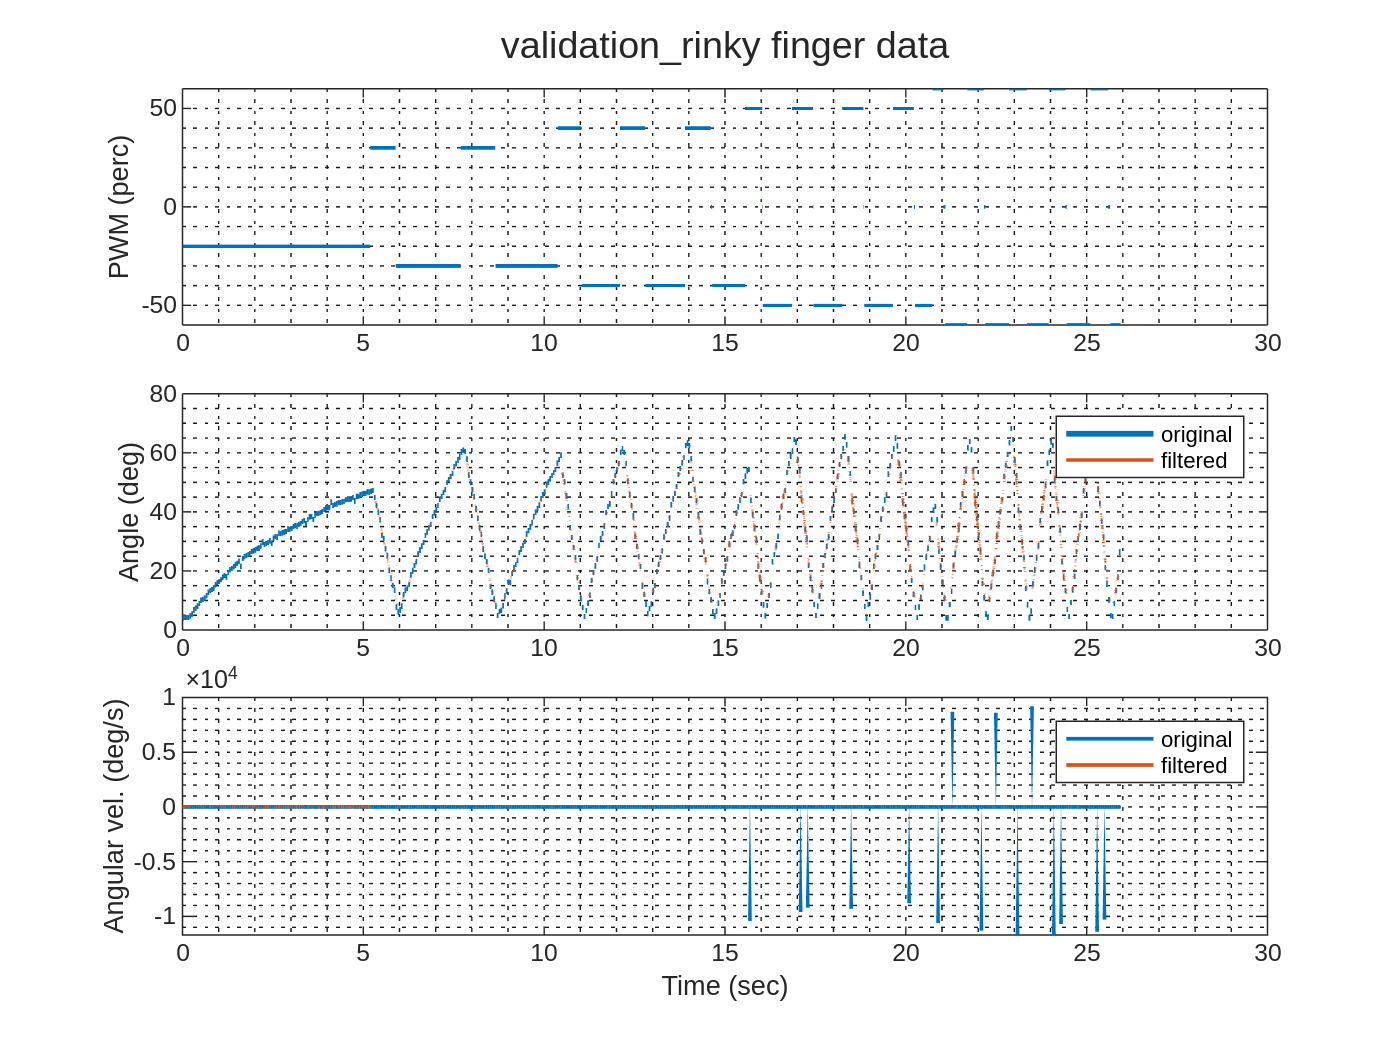

if(~exist('valid_name', 'var') ||  ~exist('valid_path', 'var'))
    [valid_name, valid_path] = uigetfile('*');
end
[pathstr, nameFile, ext] = fileparts(valid_name);

filter_constant = 50;
% validation_table = prepare_dataset(fullfile(valid_path, valid_name), Ts, filter_constant);
[validation_table, Ts] = Reshape_dataset(fullfile(valid_path, valid_name), filter_constant, 0, 0, 3);

validation_data = iddata(validation_table.vel, validation_table.pwm, Ts);
validation_data.Name = "validation";

figure('color', 'white');
tiledlayout(3,1, "TileSpacing", "tight")

h1 = nexttile;
plot(validation_table.Time, validation_table.pwm);
ylabel("PWM (perc)")
h2 = nexttile;
plot(validation_table.Time, validation_table.pos_uf,'LineWidth',2);
hold on
plot(validation_table.Time, validation_table.pos,'LineWidth',1.2);
ylabel("Angle (deg)")
legend({"original", "filtered"})
h3 = nexttile;
plot(validation_table.Time, validation_table.vel_uf);
hold on
plot(validation_table.Time, validation_table.vel);

legend({"original", "filtered"})
ylabel("Angular vel. (deg/s)")
xlabel("Time (sec)")

linkaxes([h1 h2 h3], 'x')
sgtitle(nameFile + " finger data", interpreter="none")

### Run identification as process model

We target a continuous LTI model in the form


$$G(s) = \frac{k (s - z_1)}{(s - p_1) ( s - p_2)}$$


The poles can be real or complex conjugate. 

opt = procestOptions;
opt.InitialCondition =  "zero";
model = procest(training_data, "P2ZU", opt);

s = tf('s');
finger_tf = tf(model);
zpk(finger_tf)


ans =
 
  From input "u1" to output "y1":
  -26.253 (s+0.08375)
  -------------------
  (s+14.36) (s+1.044)
 
Continuous-time zero/pole/gain model.
Model Properties


Plot results.

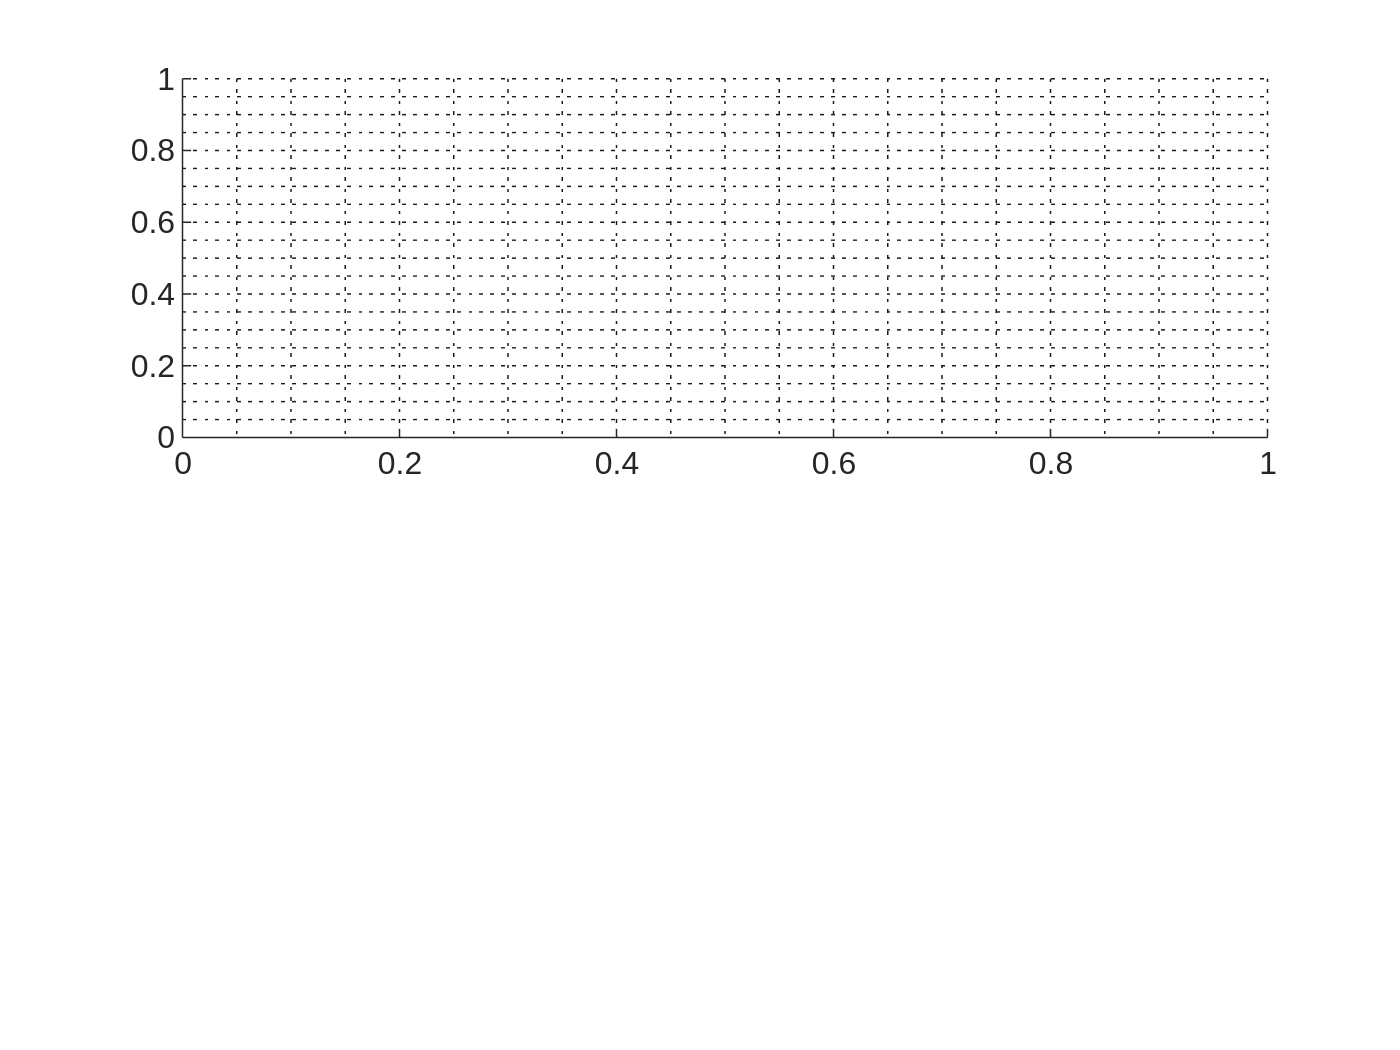

[rmse, fig_handle] = plot_results(finger_tf, training_data, validation_data, Ts, Ts);

disp(rmse)
finger_zpk = zpk(finger_tf);
poles = finger_zpk.P{1};
zeros = finger_zpk.Z{1};
k = finger_zpk.K;

tfu = k;

if(isreal(poles) && isreal(zeros))
    perc_uncertainty = 20;
    
    disp("Adding " + string(perc_uncertainty) + "% uncertainty to TF roots");

    for i=1:length(poles)
        upole = ureal("p" + string(i), poles(i), "Percentage", [-perc_uncertainty, perc_uncertainty]);
        tfu = tfu / (s - upole);
    end
    for i=1:length(zeros)
        uzero = ureal("z" + string(i), zeros(i), "Percentage", [-perc_uncertainty, perc_uncertainty]);
        tfu = tfu * (s - uzero);
    end
else
    tfu = finger_zpk;
end

### Add integrator for position control

We change the IO relationship from  $\frac{\dot{\theta} }{u}$ to $\frac{\theta }{u}$  since we want to control the finger position.

tfu = tfu / s;

## Run autotuning

Here we define the specifications to tune the position controller in a robust way, and run the tuning algorithm.

#### Define tuning goals

Define the desired specifications.

select = 3;

switch select

    case (1)
        parSet = '001';
        disp('option 1 - SN 001')
        Ts_controller = 1e-3;   % sec
        responsetime = 0.25;     % sec
        dcerror = 0.001;        % perc
        peakerror = 1.02;       % fract relative
        maxOvershoot = 2;       % perc
        phase_margin = 80;      % deg
        gain_margin = 3;        % dB
    case (2) % for now equal to SN 001
        disp('option 2 - SN 002')
        parSet = '002';
        Ts_controller = 1e-3;   % sec
        responsetime = 0.4;     % sec
        dcerror = 0.001;        % perc
        peakerror = 1.00;       % fract relative
        maxOvershoot = 0;       % perc
        phase_margin = 80;      % deg
        gain_margin = 3;        % dB
    case (3) %choose this one to play with parameters
        disp('option 3 - custom')
        parSet = 'cus';
        Ts_controller = Ts;   % sec
        responsetime = 0.1;     % sec
        dcerror = 0.0001;        % perc
        peakerror = 1.02;       % fract relative
        maxOvershoot = 2;       % perc
        phase_margin = 80;      % deg
        gain_margin = 3;        % dB
end

option 3 - custom


par_summ = strcat('Ts controller: ', num2str(Ts_controller), ...
    ', responsetime: ', num2str(responsetime), ...
    ', dcerror: ', num2str(dcerror), ...
    ', peakerror: ', num2str(peakerror), ...
    ', Overshoot: ', num2str(maxOvershoot) );
disp(par_summ);

Ts controller:0.001, responsetime:0.1, dcerror:0.0001, peakerror:1.02, Overshoot:2


#### Define the goals.

tfu.InputName = "u";
tfu.OutputName = "y";

Rtrack = TuningGoal.Tracking('r', 'y', responsetime, dcerror, peakerror);
Rov = TuningGoal.Overshoot('r', 'y', maxOvershoot);
Rmargin = TuningGoal.Margins('y', gain_margin, phase_margin);

hard_goals = Rtrack;
soft_goals = [Rmargin, Rov];

disp('hard_goals: tracking ');

hard_goals: tracking 


disp('soft_goals: margin, overshoot');

soft_goals: margin, overshoot


#### Tune up the controller

pid_type = 'PID';

[C, T] = design_robust_pid(tfu, soft_goals, hard_goals, pid_type);

Nominal tuning:
Design 1: Soft = 1.22, Hard = 1.1511
Design 2: Soft = 1.35, Hard = 1.1512
Design 3: Soft = 1.32, Hard = 1.1512
Design 4: Soft = 1.15, Hard = 1.1519
Design 5: Soft = 1.22, Hard = 1.1511
Design 6: Soft = 1.32, Hard = 1.1512
Design 7: Soft = 1.17, Hard = 1.1513
Design 8: Soft = 1.23, Hard = 1.1511
Design 9: Soft = 1.33, Hard = 1.1512
Design 10: Soft = 1.25, Hard = 1.1511
Design 11: Soft = 1.25, Hard = 1.1511

Robust tuning of Design 11:
Soft: [1.25,Inf], Hard: [1.15,1.42], Iterations = 37
Soft: [1.44,Inf], Hard: [1.16,1.19], Iterations = 26
Soft: [1.63,Inf], Hard: [1.19,1.19], Iterations = 21
Final: Soft = 1.63, Hard = 1.1854, Iterations = 84

Robust tuning of Design 10:
Soft: [1.25,Inf], Hard: [1.15,1.42], Iterations = 37
Soft: [1.45,Inf], Hard: [1.16,1.19], Iterations = 27
Soft: [1.63,Inf], Hard: [1.19,1.19], Iterations = 21
Final: Soft = 1.63, Hard = 1.1854, Iterations = 85

Robust tuning of Design 8:
Soft: [1.23,Inf], Hard: [1.15,1.44], Iterations = 37
Soft: [1.45,Inf]

Plot tuning results.

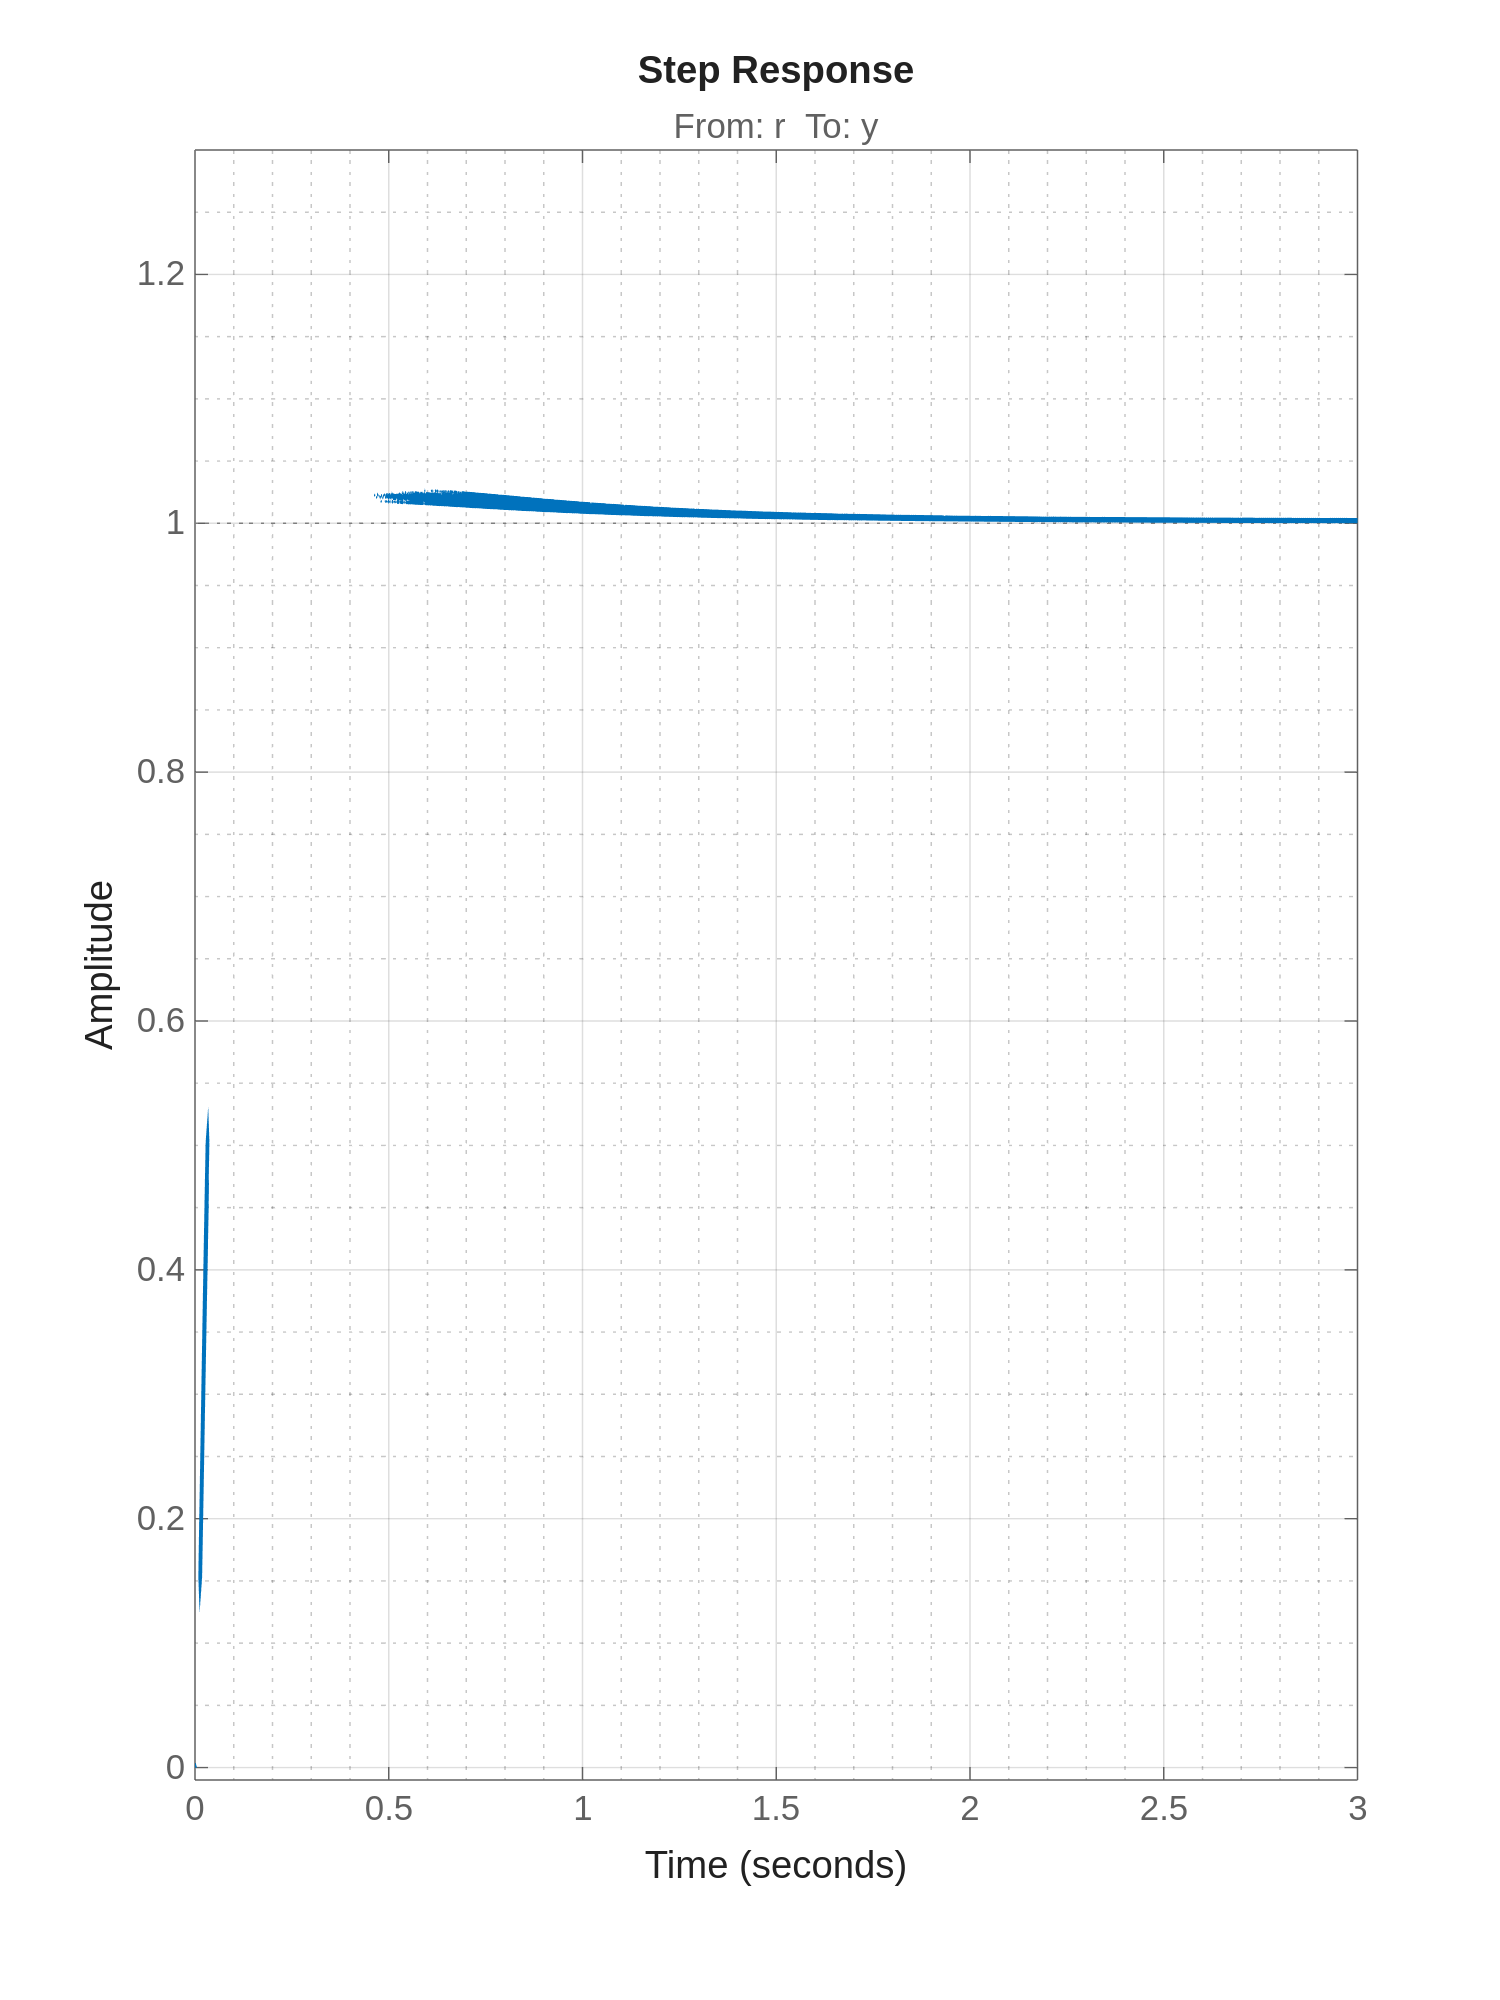

f_step = figure('color', 'white','Position',[10 10 900 1200]);
step(T, 3);
ylim([-0.01, 1.3])
grid('minor');

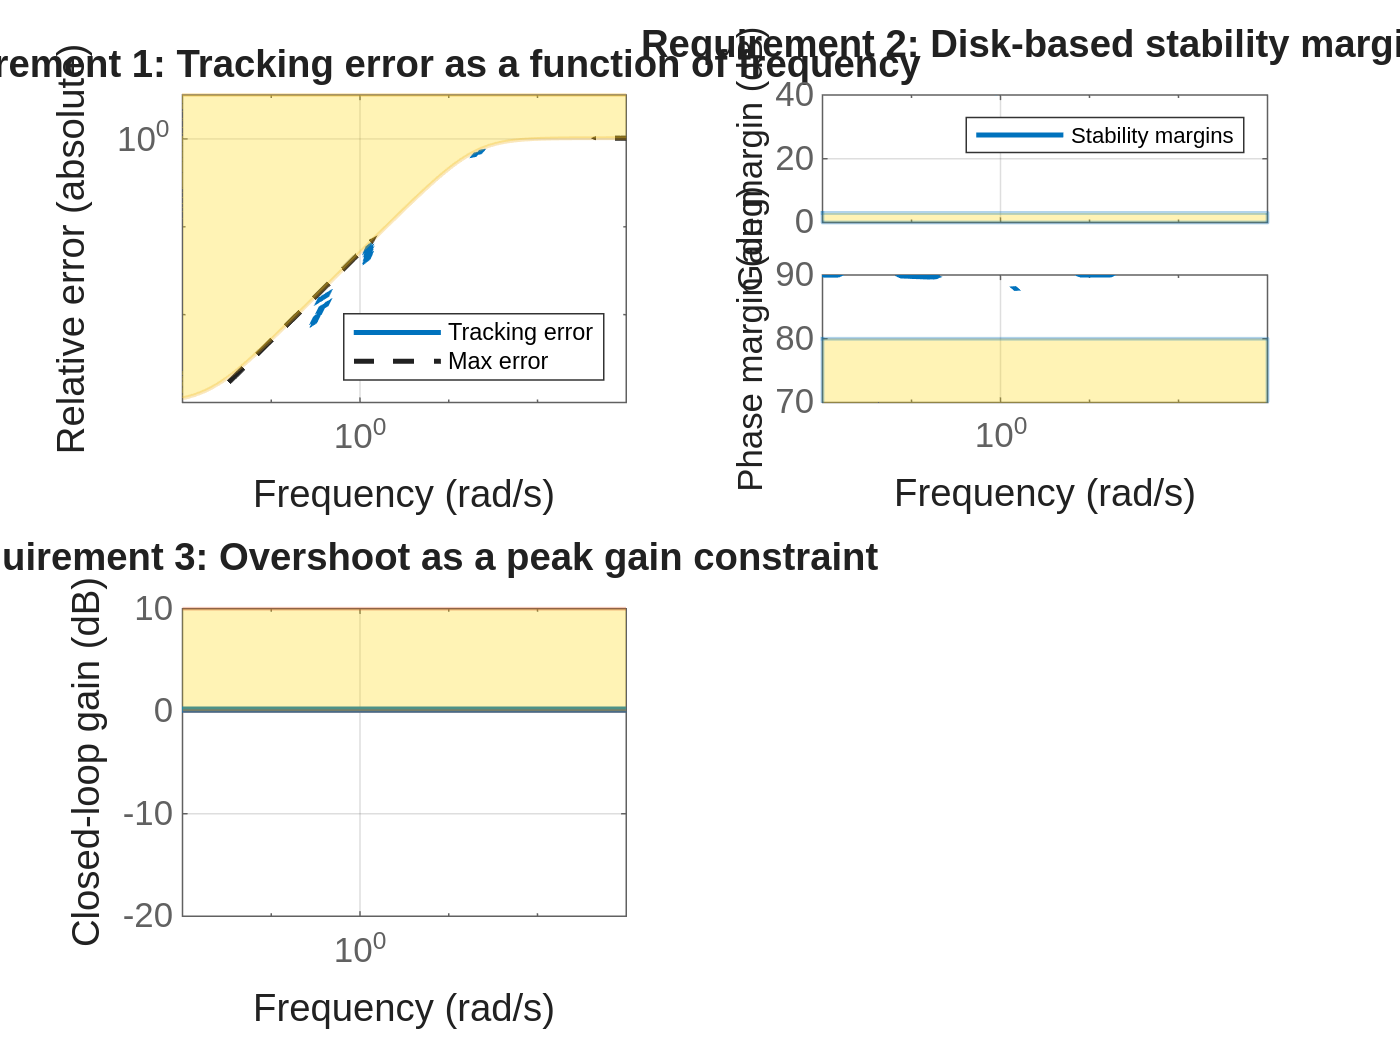

f_plots = figure('color', 'white');

viewGoal([hard_goals soft_goals], T)

Get the discretized controller.

Cz = c2d(C, Ts_controller, 'tustin');
table(["Proportional", "Integral", "Derivative"]', [Cz.Kp Cz.Ki Cz.Kd]', VariableNames = ["Param", "Value"])

ans = 3×2 table
        Param               Value      
    ______________    _________________

    "Proportional"    -11.5456244275636
    "Integral"        -17.4733423564472
    "Derivative"      -0.90896468840909


% saveas(f_train, f_name);
% exportgraphics(f_train, f_name);
% exportgraphics(f_resume, f_name,'append',true);
% exportgraphics(f_plots, f_name,'append',true);
kappapi = Cz.Kp;
kappai = Cz.Ki;
kappadi = Cz.Kd;

%to save the kp, ki and kd coefficents uncomment the following line
%save(strcat('results/', nameFile,'-',parSet,'_',tYpe,'.mat'), 'nameFile','kappapi', 'kappai','kappadi')
% writematrix([nameFile , num2str(kappapi) , num2str(kappai) , num2str(kappadi)],strcat('results/', nameFile,'-',parSet,'_',tYpe,'.csv'))

% to obtain a pdf report uncomment the following  line 
% export('identification_tuning_v2.mlx',strcat('results/',nameFile,'-',parSet,'_',tYpe,'.pdf'), Format = "pdf", HideCode = true);